F1=8000;
F=[1000 1300 2210 2410]

F =         1000        1300        2210        2410


ma=[0 1 0];
devs=[0.01 0.05 0.01];
[n,wA23,bt,Yp]=kaiserord(F,ma,devs,F1);
n=n+rem(n,2)

n = 90

bandpassfilter=fir1(n,wA23,'bandpass',kaiser(n+1,bt),'noscale');
[h,w]=freqz(bandpassfilter,1,1024,F1);
figure(6)
subplot(311)
plot(w*10000*0.5/pi,abs(h));
title('DESIGN FIR BAND PASS FILTER','fontWeight','bold');
grid;
signal_5=fftfilt(bandpassfilter,with_noise1)

signal_5 =     0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


sound(signal_5,F1);
sound(signal_5);
signal_5=fft(signal_5)

signal_5 =    0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0001 - 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0001 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 - 0.0000i


subplot(312)
plot(abs(signal_5),'r');
title('FILTRED SIGNAL WITH NOISE SNR 99');
signal_6=fftfilt(bandpassfilter,with_noise2);
sound(signal_6);
subplot(313)
Signal6=fft(signal_6)

Signal6 =    0.0092 + 0.0000i
  -0.0055 - 0.0233i
  -0.0486 + 0.0048i
  -0.0201 - 0.0116i
  -0.0523 + 0.0222i
  -0.0367 - 0.0131i
   0.0070 + 0.0512i
   0.0152 - 0.0287i
  -0.0287 + 0.0175i
   0.0082 + 0.0658i


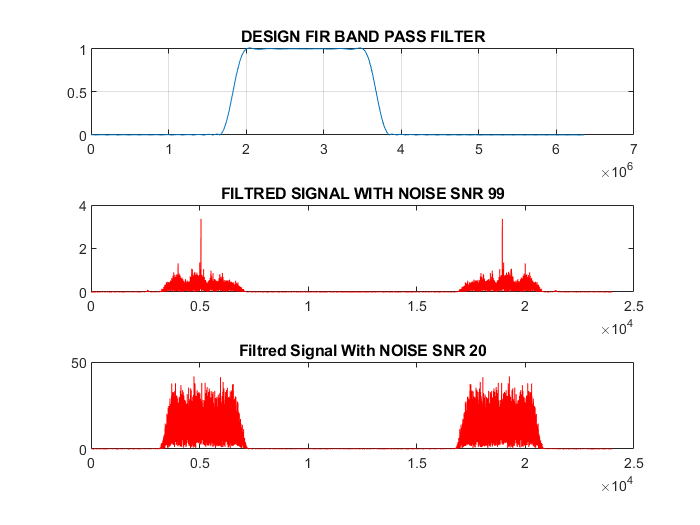

plot(abs(Signal6),'r');
title('Filtred Signal With NOISE SNR 20');

subplot(3,1,3)